# ALL BLAND_ALTMAN

num_trials = 8;
colors = ['o','b','g','r','c','m','y','k'];

min_peak_params = [
    10, 120;
    100, 1100;
    15, 400;
    100, 1100;
    15, 400;
    35, 600;
    15, 400;
    15, 400;
];

ALL_MeanBA = [];
ALL_DiffBA = [];
ALL_TrialID = [];
ALL_A_peaks = [];
ALL_B_peaks = [];
ALL_TargetMoment = [];

figure; 
hold on;

for trial = 1:num_trials

    if trial == 1
        T_Est = abs(Torque_GRF_01);
        T_Dyn = abs(Torque_dynamometer_shifted);
    elseif trial == 2
        T_Est = abs(Torque_GRF_02);
        T_Dyn = abs(Torque_dynamometer_100Hz_02(810:end));
    elseif trial == 3
        T_Est = abs(Torque_GRF_03);
        T_Dyn = abs(Torque_dynamometer_shifted_03);
    elseif trial == 4
        T_Est = abs(Torque_GRF_04);
        T_Dyn = abs(Torque_dynamometer_100Hz_04(1000:end));
    elseif trial == 5
        T_Est = abs(Torque_GRF_05);
        T_Dyn = abs(Torque_dynamometer_100Hz_05(3630:end));
    elseif trial == 6
        T_Est = abs(Torque_GRF_06);
        T_Dyn = abs(Torque_dynamometer_shifted_06);
    elseif trial == 7
        T_Est = abs(Torque_GRF_07);
        T_Dyn = abs(Torque_dynamometer_100Hz_07(1010:end));
    elseif trial == 8
        T_Est = abs(Torque_GRF_08);
        T_Dyn = abs(Torque_dynamometer_100Hz_08(1420:end));
    end

    min_len = min(length(T_Est), length(T_Dyn));
    T_Est = T_Est(1:min_len);
    T_Dyn = T_Dyn(1:min_len);

    min_peak_height   = min_peak_params(trial, 1);
    min_peak_distance = min_peak_params(trial, 2);

    [pks_B, locs_B] = findpeaks(T_Dyn, ...
        'MinPeakHeight', min_peak_height, ...
        'MinPeakDistance', min_peak_distance);
    
    target_moment = zeros(size(pks_B));

    threshold = 40; 

    for i = 1:length(pks_B)
       if pks_B(i) < threshold
        target_moment(i) = 25;
        else
        target_moment(i) = 50;
       end
    end

    pks_A = T_Est(locs_B);

    valid = (pks_A > 0) & (pks_B > 0);
    A = pks_A(valid);   
    B = pks_B(valid);   

    % Bland–Altman 
    MeanBA = (A + B) / 2;
    DiffBA = (A - B);

    target_moment = target_moment(valid);  

    scatter(MeanBA, DiffBA, 35, colors(trial), 'filled');

    ALL_MeanBA = [ALL_MeanBA; MeanBA(:)];
    ALL_DiffBA = [ALL_DiffBA; DiffBA(:)];
    ALL_TrialID = [ALL_TrialID; trial*ones(numel(DiffBA),1)];
    ALL_A_peaks = [ALL_A_peaks; A(:)];
    ALL_B_peaks = [ALL_B_peaks; B(:)];
    ALL_TargetMoment = [ALL_TargetMoment; target_moment(:)];
end

% MAPE
MAPE_peaks = mean(abs((ALL_A_peaks - ALL_B_peaks) ./ ALL_B_peaks)) * 100;

% RMSE (peaks) 
RMSE_peaks = sqrt(mean((ALL_A_peaks - ALL_B_peaks).^2));

% CV (peaks) 
diff_peaks = ALL_A_peaks - ALL_B_peaks;
TE_peaks = std(diff_peaks) / sqrt(2);
CV_peaks = (TE_peaks / mean(ALL_B_peaks)) * 100;

fprintf('PEAKS: MAPE=%.2f%% | RMSE=%.2f Nm | CV=%.2f%% (TE=%.2f Nm)\n', ...
    MAPE_peaks, RMSE_peaks, CV_peaks, TE_peaks);

PEAKS: MAPE=5.57% | RMSE=2.89 Nm | CV=3.61% (TE=2.05 Nm)


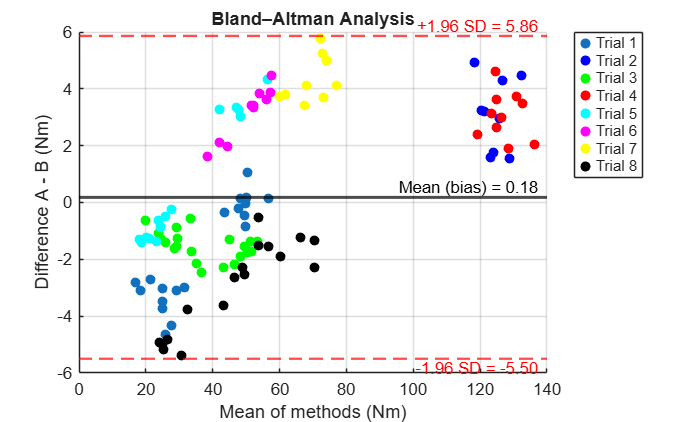

bias = mean(ALL_DiffBA);
sdDiff = std(ALL_DiffBA);
loa_upper = bias + 1.96*sdDiff;
loa_lower = bias - 1.96*sdDiff;

inside = mean(ALL_DiffBA >= loa_lower & ALL_DiffBA <= loa_upper) * 100;

hBias  = yline(bias, 'k-',  'LineWidth', 1.8);
hUpper = yline(loa_upper, 'r--','LineWidth', 1.4);
hLower = yline(loa_lower, 'r--','LineWidth', 1.4);

grid on;
xlabel('Mean of methods (Nm)');
ylabel('Difference A - B (Nm)');
title('Bland–Altman Analysis');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8', 'Location','bestoutside');
xL = xlim;
xR = xL(2);                    
xText = xR - 0.02*(xL(2)-xL(1));

text(xText, loa_upper, sprintf('+1.96 SD = %.2f', loa_upper), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','r', 'FontSize',10);

text(xText, bias, sprintf('Mean (bias) = %.2f', bias), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','k', 'FontSize',10);

text(xText, loa_lower, sprintf('-1.96 SD = %.2f', loa_lower), ...
    'HorizontalAlignment','right', 'VerticalAlignment','top', ...
    'Color','r', 'FontSize',10);

fprintf('\nGLOBAL BA: bias = %.2f Nm, LoA = [%.2f, %.2f] Nm, inside = %.1f%% (N=%d)\n', ...
    bias, loa_lower, loa_upper, inside, numel(ALL_DiffBA));


GLOBAL BA: bias = 0.18 Nm, LoA = [-5.50, 5.86] Nm, inside = 100.0% (N=110)


% PROPORTIONAL BIAS TEST (BA REGRESSION) 
X = ALL_MeanBA(:);
Y = ALL_DiffBA(:);

mdl = fitlm(X, Y);   % Y = b0 + b1*X
beta0 = mdl.Coefficients.Estimate(1);
beta1 = mdl.Coefficients.Estimate(2);
p_beta1 = mdl.Coefficients.pValue(2);
CI = coefCI(mdl, 0.05);   % 95% CI
CI_beta1 = CI(2,:);

fprintf('\nProportional bias test (BA regression):\n');


Proportional bias test (BA regression):


fprintf('Diff = %.3f + %.5f * Mean\n', beta0, beta1);

Diff = -2.886 + 0.05391 * Mean


fprintf('beta1 = %.5f (95%% CI %.5f to %.5f), p = %.3g, R^2 = %.3f\n', ...
    beta1, CI_beta1(1), CI_beta1(2), p_beta1, mdl.Rsquared.Ordinary);

beta1 = 0.05391 (95% CI 0.04190 to 0.06593), p = 1.48e-14, R^2 = 0.423


Practical meaning: change in bias over 100 Nm = 5.39 Nm


tbl = table(ALL_DiffBA, ALL_MeanBA, categorical(ALL_TrialID), ...
    'VariableNames', {'Diff','Mean','Trial'});

lme = fitlme(tbl,'Diff ~ Mean + (1|Trial)');

disp(lme)


Linear mixed-effects model fit by ML

Model information:
    Number of observations             110
    Fixed effects coefficients           2
    Random effects coefficients          8
    Covariance parameters                2

Formula:
    Diff ~ 1 + Mean + (1 | Trial)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    355.54    366.35    -173.77          347.54  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF     pValue        Lower       Upper   
    {'(Intercept)'}         -4.4919      1.0269    -4.3743    108    2.8187e-05     -6.5274     -2.4565
    {'Mean'       }        0.083699    0.008184     10.227    108    1.4174e-17    0.067477    0.099921

Random effects covariance parameters (95% CIs):
Group: Trial (8 Levels)
    Name1                  Name2                  Type           Estimate    

## BA - TRIAL 1 & 2

ALL_MeanBA = [];
ALL_DiffBA = [];
ALL_TrialID = [];
ALL_A_peaks = [];
ALL_B_peaks = [];

figure;
hold on;

for trial = 1:2

    if trial == 1
        T_Est = abs(Torque_GRF_01);
        T_Dyn = abs(Torque_dynamometer_shifted);
    elseif trial == 2
        T_Est = abs(Torque_GRF_02);
        T_Dyn = abs(Torque_dynamometer_100Hz_02(810:end));
    end

    min_len = min(length(T_Est), length(T_Dyn));
    T_Est = T_Est(1:min_len);
    T_Dyn = T_Dyn(1:min_len);

    % Contrex Peaks
    min_peak_height   = min_peak_params(trial, 1);
    min_peak_distance = min_peak_params(trial, 2);

    [pks_B, locs_B] = findpeaks(T_Dyn, ...
        'MinPeakHeight', min_peak_height, ...
        'MinPeakDistance', min_peak_distance);

    pks_A = T_Est(locs_B);

    valid = (pks_A > 0) & (pks_B > 0);
    A = pks_A(valid);   % estimated
    B = pks_B(valid);   % Contrex

    % Bland-Altman
    MeanBA = (A + B) / 2;
    DiffBA = (A - B);
    scatter(MeanBA, DiffBA, 35, colors(trial), 'filled');
    ALL_MeanBA = [ALL_MeanBA; MeanBA(:)];
    ALL_DiffBA = [ALL_DiffBA; DiffBA(:)];
    ALL_TrialID = [ALL_TrialID; trial*ones(numel(DiffBA),1)];
    ALL_A_peaks = [ALL_A_peaks; A(:)];
    ALL_B_peaks = [ALL_B_peaks; B(:)];
end

% MAPE (peaks) 
MAPE_peaks = mean(abs((ALL_A_peaks - ALL_B_peaks) ./ ALL_B_peaks)) * 100;

% RMSE (peaks) 
RMSE_peaks = sqrt(mean((ALL_A_peaks - ALL_B_peaks).^2));

% CV (peaks) 
diff_peaks = ALL_A_peaks - ALL_B_peaks;
TE_peaks = std(diff_peaks) / sqrt(2);
MBE_peaks = (bias / mean(ALL_B_peaks)) * 100;
CV_peaks = (TE_peaks / mean(ALL_B_peaks)) * 100;

fprintf('PEAKS: MAPE=%.2f%% | RMSE=%.2f Nm | CV=%.2f%% | MBE=%.2f%%\n', ...
    MAPE_peaks, RMSE_peaks, CV_peaks, MBE_peaks);

PEAKS: MAPE=5.75% | RMSE=2.81 Nm | CV=3.11% | MBE=0.28%


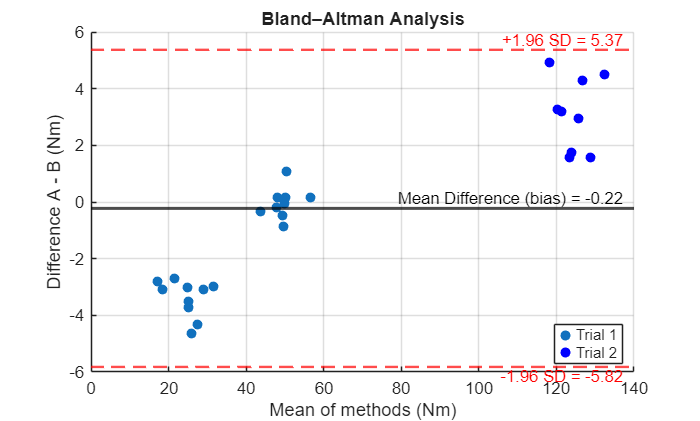

bias = mean(ALL_DiffBA);
sdDiff = std(ALL_DiffBA);
loa_upper = bias + 1.96*sdDiff;
loa_lower = bias - 1.96*sdDiff;
inside = mean(ALL_DiffBA >= loa_lower & ALL_DiffBA <= loa_upper) * 100;

hBias  = yline(bias, 'k-',  'LineWidth', 1.8);
hUpper = yline(loa_upper, 'r--','LineWidth', 1.4);
hLower = yline(loa_lower, 'r--','LineWidth', 1.4);

grid on;
xlabel('Mean of methods (Nm)');
ylabel('Difference A - B (Nm)');
title('Bland–Altman Analysis');
legend('Trial 1','Trial 2', 'Location','best');

xL = xlim;
xR = xL(2);                    
xText = xR - 0.02*(xL(2)-xL(1)); 

text(xText, loa_upper, sprintf('+1.96 SD = %.2f', loa_upper), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','r', 'FontSize',10);

text(xText, bias, sprintf('Mean Difference (bias) = %.2f', bias), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','k', 'FontSize',10);

text(xText, loa_lower, sprintf('-1.96 SD = %.2f', loa_lower), ...
    'HorizontalAlignment','right', 'VerticalAlignment','top', ...
    'Color','r', 'FontSize',10);

fprintf('\nGLOBAL BA: bias = %.2f Nm, LoA = [%.2f, %.2f] Nm, inside = %.1f%% (N=%d)\n', ...
    bias, loa_lower, loa_upper, inside, numel(ALL_DiffBA));


GLOBAL BA: bias = -0.22 Nm, LoA = [-5.82, 5.37] Nm, inside = 100.0% (N=28)


% PROPORTIONAL BIAS TEST (BA REGRESSION) - TRIAL 1-2 

X = ALL_MeanBA(:);
Y = ALL_DiffBA(:);

mdl = fitlm(X, Y);   % Diff = b0 + b1*Mean
beta0 = mdl.Coefficients.Estimate(1);
beta1 = mdl.Coefficients.Estimate(2);
p_beta1 = mdl.Coefficients.pValue(2);
CI = coefCI(mdl, 0.05);        % 95% CI
CI_beta1 = CI(2,:);

fprintf('\n[Trials 1-2] Proportional bias test (BA regression):\n');


[Trials 1-2] Proportional bias test (BA regression):


fprintf('Diff = %.3f + %.5f * Mean\n', beta0, beta1);

Diff = -4.091 + 0.05972 * Mean


fprintf('beta1 = %.5f (95%% CI %.5f to %.5f), p = %.3g, R^2 = %.3f\n', ...
    beta1, CI_beta1(1), CI_beta1(2), p_beta1, mdl.Rsquared.Ordinary);

beta1 = 0.05972 (95% CI 0.04857 to 0.07087), p = 2.78e-11, R^2 = 0.823


Practical meaning: change in bias over observed torque range (115.4 Nm) = 6.89 Nm


% MIXED-EFFECTS (accounts for within-trial clustering) - TRIAL 1-2 
% Note: only meaningful if TrialID contains at least 2 levels (here: yes, 1 and 2)

tbl = table(Y, X, categorical(ALL_TrialID), 'VariableNames', {'Diff','Mean','Trial'});
lme = fitlme(tbl, 'Diff ~ Mean + (1|Trial)');

fprintf('\n[Trials 1-2] Mixed-effects model (random intercept by Trial):\n');


[Trials 1-2] Mixed-effects model (random intercept by Trial):


disp(lme);


Linear mixed-effects model fit by ML

Model information:
    Number of observations              28
    Fixed effects coefficients           2
    Random effects coefficients          2
    Covariance parameters                2

Formula:
    Diff ~ 1 + Mean + (1 | Trial)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    97.744    103.07    -44.872          89.744  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF    pValue        Lower       Upper  
    {'(Intercept)'}        -7.4177       1.8755    -3.9551    26    0.00052548     -11.273    -3.5626
    {'Mean'       }        0.10049     0.015677     6.4101    26    8.6205e-07    0.068268    0.13272

Random effects covariance parameters (95% CIs):
Group: Trial (2 Levels)
    Name1                  Name2                  Type           Estimate    Lower 

## BA - TRIAL 3 & 4

ALL_MeanBA = [];
ALL_DiffBA = [];
ALL_TrialID = [];
ALL_A_peaks = [];
ALL_B_peaks = [];

figure; 
hold on;

for trial = 3:4

    if  trial == 3
        T_Est = abs(Torque_GRF_03);
        T_Dyn = abs(Torque_dynamometer_shifted_03);
    elseif trial == 4
        T_Est = abs(Torque_GRF_04);
        T_Dyn = abs(Torque_dynamometer_100Hz_04(1000:end));
    end

    min_len = min(length(T_Est), length(T_Dyn));
    T_Est = T_Est(1:min_len);
    T_Dyn = T_Dyn(1:min_len);

    min_peak_height   = min_peak_params(trial, 1);
    min_peak_distance = min_peak_params(trial, 2);

    [pks_B, locs_B] = findpeaks(T_Dyn, ...
        'MinPeakHeight', min_peak_height, ...
        'MinPeakDistance', min_peak_distance);

    pks_A = T_Est(locs_B);

    valid = (pks_A > 0) & (pks_B > 0);
    A = pks_A(valid);  
    B = pks_B(valid);  

    MeanBA = (A + B) / 2;
    DiffBA = (A - B);

    scatter(MeanBA, DiffBA, 35, colors(trial), 'filled');
    ALL_MeanBA = [ALL_MeanBA; MeanBA(:)];
    ALL_DiffBA = [ALL_DiffBA; DiffBA(:)];
    ALL_TrialID = [ALL_TrialID; trial*ones(numel(DiffBA),1)];
    ALL_A_peaks = [ALL_A_peaks; A(:)];
    ALL_B_peaks = [ALL_B_peaks; B(:)];
end

% MAPE (peaks) 
MAPE_peaks = mean(abs((ALL_A_peaks - ALL_B_peaks) ./ ALL_B_peaks)) * 100;

% RMSE (peaks) 
RMSE_peaks = sqrt(mean((ALL_A_peaks - ALL_B_peaks).^2));

% CV (peaks) 
diff_peaks = ALL_A_peaks - ALL_B_peaks;
TE_peaks = std(diff_peaks) / sqrt(2);
CV_peaks = (TE_peaks / mean(ALL_B_peaks)) * 100;

fprintf('PEAKS: MAPE=%.2f%% | RMSE=%.2f Nm | CV=%.2f%% (TE=%.2f Nm)\n', ...
    MAPE_peaks, RMSE_peaks, CV_peaks, TE_peaks);

PEAKS: MAPE=3.57% | RMSE=2.23 Nm | CV=2.41% (TE=1.60 Nm)


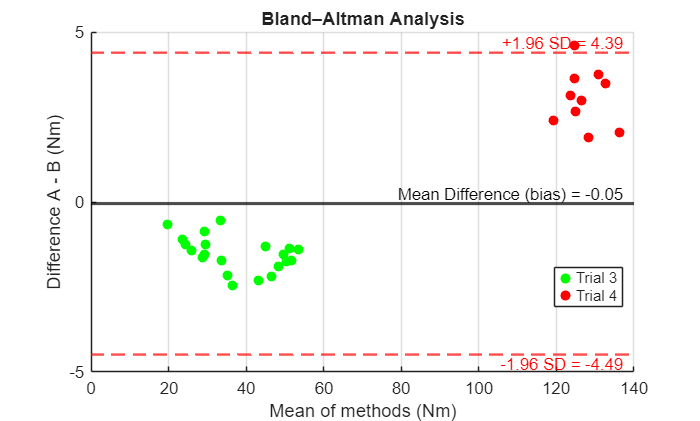

bias = mean(ALL_DiffBA);
sdDiff = std(ALL_DiffBA);
loa_upper = bias + 1.96*sdDiff;
loa_lower = bias - 1.96*sdDiff;

inside = mean(ALL_DiffBA >= loa_lower & ALL_DiffBA <= loa_upper) * 100;

hBias  = yline(bias, 'k-',  'LineWidth', 1.8);
hUpper = yline(loa_upper, 'r--','LineWidth', 1.4);
hLower = yline(loa_lower, 'r--','LineWidth', 1.4);

grid on;
xlabel('Mean of methods (Nm)');
ylabel('Difference A - B (Nm)');
title('Bland–Altman Analysis');
legend('Trial 3','Trial 4', 'Location','best');

xL = xlim;
xR = xL(2);                    
xText = xR - 0.02*(xL(2)-xL(1));

text(xText, loa_upper, sprintf('+1.96 SD = %.2f', loa_upper), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','r', 'FontSize',10);

text(xText, bias, sprintf('Mean Difference (bias) = %.2f', bias), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','k', 'FontSize',10);

text(xText, loa_lower, sprintf('-1.96 SD = %.2f', loa_lower), ...
    'HorizontalAlignment','right', 'VerticalAlignment','top', ...
    'Color','r', 'FontSize',10);

fprintf('\nGLOBAL BA: bias = %.2f Nm, LoA = [%.2f, %.2f] Nm, inside = %.1f%% (N=%d)\n', ...
    bias, loa_lower, loa_upper, inside, numel(ALL_DiffBA));


GLOBAL BA: bias = -0.05 Nm, LoA = [-4.49, 4.39] Nm, inside = 96.8% (N=31)


%  PROPORTIONAL BIAS TEST (BA REGRESSION) - TRIAL 3-4
X = ALL_MeanBA(:);
Y = ALL_DiffBA(:);

mdl = fitlm(X, Y);
beta0 = mdl.Coefficients.Estimate(1);
beta1 = mdl.Coefficients.Estimate(2);
p_beta1 = mdl.Coefficients.pValue(2);
CI = coefCI(mdl, 0.05);
CI_beta1 = CI(2,:);

fprintf('\n[Trials 3-4] Proportional bias test (BA regression):\n');


[Trials 3-4] Proportional bias test (BA regression):


fprintf('Diff = %.3f + %.5f * Mean\n', beta0, beta1);

Diff = -3.230 + 0.04788 * Mean


fprintf('beta1 = %.5f (95%% CI %.5f to %.5f), p = %.3g, R^2 = %.3f\n', ...
    beta1, CI_beta1(1), CI_beta1(2), p_beta1, mdl.Rsquared.Ordinary);

beta1 = 0.04788 (95% CI 0.04022 to 0.05555), p = 1.92e-13, R^2 = 0.849


Practical meaning: change in bias over 100 Nm = 4.79 Nm


tbl = table(Y, X, categorical(ALL_TrialID), 'VariableNames', {'Diff','Mean','Trial'});
lme = fitlme(tbl, 'Diff ~ Mean + (1|Trial)');

fprintf('\n[Trials 3-4] Mixed-effects model:\n');


[Trials 3-4] Mixed-effects model:


disp(lme);


Linear mixed-effects model fit by ML

Model information:
    Number of observations              31
    Fixed effects coefficients           2
    Random effects coefficients          2
    Covariance parameters                2

Formula:
    Diff ~ 1 + Mean + (1 | Trial)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    76.252    81.988    -34.126          68.252  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE         tStat      DF    pValue     Lower        Upper    
    {'(Intercept)'}           2.1162     2.3398    0.90442    29    0.37322      -2.6692       6.9015
    {'Mean'       }        -0.016435    0.01145    -1.4353    29    0.16189    -0.039853    0.0069835

Random effects covariance parameters (95% CIs):
Group: Trial (2 Levels)
    Name1                  Name2                  Type           Estimate    Lower 

## BA - Trial 5 & 6 & 7

ALL_MeanBA = [];
ALL_DiffBA = [];
ALL_TrialID = [];
ALL_A_peaks = [];
ALL_B_peaks = [];

figure; hold on;

for trial = 5:7
    if trial == 5
        T_Est = abs(Torque_GRF_05);
        T_Dyn = abs(Torque_dynamometer_100Hz_05(3630:end));
    elseif trial == 6
        T_Est = abs(Torque_GRF_06);
        T_Dyn = abs(Torque_dynamometer_shifted_06);
    elseif trial == 7
        T_Est = abs(Torque_GRF_07);
        T_Dyn = abs(Torque_dynamometer_100Hz_07(1010:end));
    end

    min_len = min(length(T_Est), length(T_Dyn));
    T_Est = T_Est(1:min_len);
    T_Dyn = T_Dyn(1:min_len);

    % Contrex Peaks
    min_peak_height   = min_peak_params(trial, 1);
    min_peak_distance = min_peak_params(trial, 2);

    [pks_B, locs_B] = findpeaks(T_Dyn, ...
        'MinPeakHeight', min_peak_height, ...
        'MinPeakDistance', min_peak_distance);

    pks_A = T_Est(locs_B);

    valid = (pks_A > 0) & (pks_B > 0);
    A = pks_A(valid);   
    B = pks_B(valid);   

    MeanBA = (A + B) / 2;
    DiffBA = (A - B);

    scatter(MeanBA, DiffBA, 35, colors(trial), 'filled');

    ALL_MeanBA = [ALL_MeanBA; MeanBA(:)];
    ALL_DiffBA = [ALL_DiffBA; DiffBA(:)];
    ALL_TrialID = [ALL_TrialID; trial*ones(numel(DiffBA),1)];
    ALL_A_peaks = [ALL_A_peaks; A(:)];
    ALL_B_peaks = [ALL_B_peaks; B(:)];
end

% MAPE (peaks)
MAPE_peaks = mean(abs((ALL_A_peaks - ALL_B_peaks) ./ ALL_B_peaks)) * 100;

% RMSE (peaks) 
RMSE_peaks = sqrt(mean((ALL_A_peaks - ALL_B_peaks).^2));

% CV (peaks)
diff_peaks = ALL_A_peaks - ALL_B_peaks;
TE_peaks = std(diff_peaks) / sqrt(2);
CV_peaks = (TE_peaks / mean(ALL_B_peaks)) * 100;

fprintf('PEAKS: MAPE=%.2f%% | RMSE=%.2f Nm | CV=%.2f%% (TE=%.2f Nm)\n', ...
    MAPE_peaks, RMSE_peaks, CV_peaks, TE_peaks);

PEAKS: MAPE=5.94% | RMSE=3.22 Nm | CV=3.53% (TE=1.62 Nm)


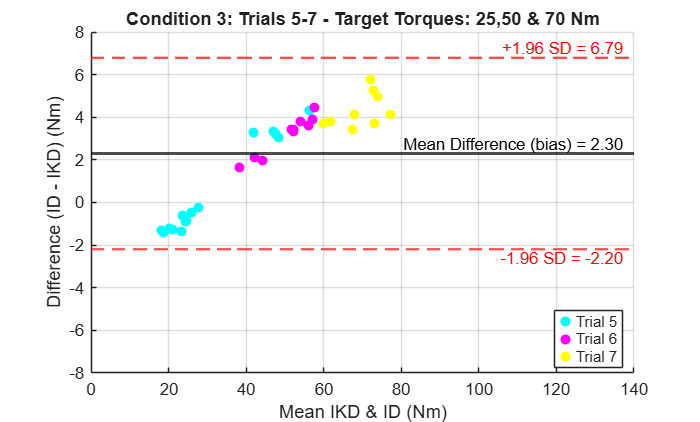

bias = mean(ALL_DiffBA);
sdDiff = std(ALL_DiffBA);
loa_upper = bias + 1.96*sdDiff;
loa_lower = bias - 1.96*sdDiff;

inside = mean(ALL_DiffBA >= loa_lower & ALL_DiffBA <= loa_upper) * 100;

hBias  = yline(bias, 'k-',  'LineWidth', 1.8);
hUpper = yline(loa_upper, 'r--','LineWidth', 1.4);
hLower = yline(loa_lower, 'r--','LineWidth', 1.4);

grid on;
xlabel('Mean IKD & ID (Nm)');
ylabel('Difference (ID - IKD) (Nm)');
title('Condition 3: Trials 5-7 - Target Torques: 25,50 & 70 Nm');
xlim([0 140]);
ylim([-8 8]);
legend('Trial 5','Trial 6','Trial 7', 'Location','best');

xL = xlim;
xR = xL(2);                    
xText = xR - 0.02*(xL(2)-xL(1)); 

text(xText, loa_upper, sprintf('+1.96 SD = %.2f', loa_upper), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','r', 'FontSize',10);

text(xText, bias, sprintf('Mean Difference (bias) = %.2f', bias), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','k', 'FontSize',10);

text(xText, loa_lower, sprintf('-1.96 SD = %.2f', loa_lower), ...
    'HorizontalAlignment','right', 'VerticalAlignment','top', ...
    'Color','r', 'FontSize',10);

fprintf('\nGLOBAL BA: bias = %.2f Nm, LoA = [%.2f, %.2f] Nm, inside = %.1f%% (N=%d)\n', ...
    bias, loa_lower, loa_upper, inside, numel(ALL_DiffBA));


GLOBAL BA: bias = 2.30 Nm, LoA = [-2.20, 6.79] Nm, inside = 100.0% (N=34)


% PROPORTIONAL BIAS TEST (BA REGRESSION) - TRIAL 5-6-7
X = ALL_MeanBA(:);
Y = ALL_DiffBA(:);

mdl = fitlm(X, Y);   % Diff = b0 + b1*Mean
beta0 = mdl.Coefficients.Estimate(1);
beta1 = mdl.Coefficients.Estimate(2);
p_beta1 = mdl.Coefficients.pValue(2);
CI = coefCI(mdl, 0.05);        % 95% CI
CI_beta1 = CI(2,:);

fprintf('\n[Trials 5-6-7] Proportional bias test (BA regression):\n');


[Trials 5-6-7] Proportional bias test (BA regression):


fprintf('Diff = %.3f + %.5f * Mean\n', beta0, beta1);

Diff = -3.176 + 0.11625 * Mean


fprintf('beta1 = %.5f (95%% CI %.5f to %.5f), p = %.3g, R^2 = %.3f\n', ...
    beta1, CI_beta1(1), CI_beta1(2), p_beta1, mdl.Rsquared.Ordinary);

beta1 = 0.11625 (95% CI 0.10174 to 0.13076), p = 4.53e-17, R^2 = 0.893


Practical meaning: change in bias over 100 Nm = 11.62 Nm


% MIXED-EFFECTS - TRIAL 5-6-7

tbl = table(Y, X, categorical(ALL_TrialID), ...
    'VariableNames', {'Diff','Mean','Trial'});

lme = fitlme(tbl, 'Diff ~ Mean + (1|Trial)');

fprintf('\n[Trials 5-6-7] Mixed-effects model (random intercept by Trial):\n');


[Trials 5-6-7] Mixed-effects model (random intercept by Trial):


disp(lme);


Linear mixed-effects model fit by ML

Model information:
    Number of observations              34
    Fixed effects coefficients           2
    Random effects coefficients          3
    Covariance parameters                2

Formula:
    Diff ~ 1 + Mean + (1 | Trial)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    72.666    78.771    -32.333          64.666  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat      DF    pValue        Lower      Upper  
    {'(Intercept)'}        -4.8561       0.67806    -7.1617    32    3.9491e-08    -6.2373    -3.4749
    {'Mean'       }        0.14907     0.0093744     15.902    32    9.5119e-17    0.12998    0.16817

Random effects covariance parameters (95% CIs):
Group: Trial (3 Levels)
    Name1                  Name2                  Type           Estimate    Lower 

## BA - Trial 8

ALL_MeanBA = [];
ALL_DiffBA = [];
ALL_TrialID = [];
ALL_A_peaks = [];
ALL_B_peaks = [];

figure;
hold on;

for trial = 8
        T_Est = abs(Torque_GRF_08);
        T_Dyn = abs(Torque_dynamometer_100Hz_08(1420:end));
end

    min_len = min(length(T_Est), length(T_Dyn));
    T_Est = T_Est(1:min_len);
    T_Dyn = T_Dyn(1:min_len);

    min_peak_height   = min_peak_params(trial, 1);
    min_peak_distance = min_peak_params(trial, 2);

    [pks_B, locs_B] = findpeaks(T_Dyn, ...
        'MinPeakHeight', min_peak_height, ...
        'MinPeakDistance', min_peak_distance);

    pks_A = T_Est(locs_B);

    valid = (pks_A > 0) & (pks_B > 0);
    A = pks_A(valid);  
    B = pks_B(valid);  

    MeanBA = (A + B) / 2;
    DiffBA = (A - B);

    scatter(MeanBA, DiffBA, 35, colors(trial), 'filled');

    ALL_MeanBA = [ALL_MeanBA; MeanBA(:)];
    ALL_DiffBA = [ALL_DiffBA; DiffBA(:)];
    ALL_TrialID = [ALL_TrialID; trial*ones(numel(DiffBA),1)];
    ALL_A_peaks = [ALL_A_peaks; A(:)];
    ALL_B_peaks = [ALL_B_peaks; B(:)];


% MAPE (peaks) 
MAPE_peaks = mean(abs((ALL_A_peaks - ALL_B_peaks) ./ ALL_B_peaks)) * 100;

% RMSE (peaks) 
RMSE_peaks = sqrt(mean((ALL_A_peaks - ALL_B_peaks).^2));

% CV (peaks) 
diff_peaks = ALL_A_peaks - ALL_B_peaks;
TE_peaks = std(diff_peaks) / sqrt(2);
CV_peaks = (TE_peaks / mean(ALL_B_peaks)) * 100;

fprintf('PEAKS: MAPE=%.2f%% | RMSE=%.2f Nm | CV=%.2f%% ', ...
    MAPE_peaks, RMSE_peaks, CV_peaks);

PEAKS: MAPE=8.17% | RMSE=3.35 Nm | CV=2.39% 

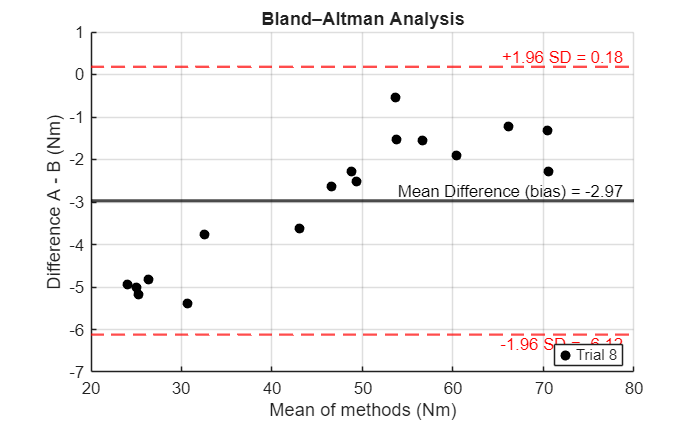

bias = mean(ALL_DiffBA);
sdDiff = std(ALL_DiffBA);
loa_upper = bias + 1.96*sdDiff;
loa_lower = bias - 1.96*sdDiff;

inside = mean(ALL_DiffBA >= loa_lower & ALL_DiffBA <= loa_upper) * 100;

hBias  = yline(bias, 'k-',  'LineWidth', 1.8);
hUpper = yline(loa_upper, 'r--','LineWidth', 1.4);
hLower = yline(loa_lower, 'r--','LineWidth', 1.4);

grid on;
xlabel('Mean of methods (Nm)');
ylabel('Difference A - B (Nm)');
title('Bland–Altman Analysis');
legend('Trial 8', 'Location','best');

xL = xlim;
xR = xL(2);                    
xText = xR - 0.02*(xL(2)-xL(1)); 

text(xText, loa_upper, sprintf('+1.96 SD = %.2f', loa_upper), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','r', 'FontSize',10);

text(xText, bias, sprintf('Mean Difference (bias) = %.2f', bias), ...
    'HorizontalAlignment','right', 'VerticalAlignment','bottom', ...
    'Color','k', 'FontSize',10);

text(xText, loa_lower, sprintf('-1.96 SD = %.2f', loa_lower), ...
    'HorizontalAlignment','right', 'VerticalAlignment','top', ...
    'Color','r', 'FontSize',10);


fprintf('\nGLOBAL BA: bias = %.2f Nm, LoA = [%.2f, %.2f] Nm, inside = %.1f%% (N=%d)\n', ...
    bias, loa_lower, loa_upper, inside, numel(ALL_DiffBA));


GLOBAL BA: bias = -2.97 Nm, LoA = [-6.12, 0.18] Nm, inside = 100.0% (N=17)


% REGRESSION Trial 8

% Mean of A and B
MeanBA = (ALL_A_peaks + ALL_B_peaks)/2;
DiffBA = ALL_A_peaks - ALL_B_peaks;

% Regression: Diff vs Mean
X = MeanBA(:);        % Mean of estimated and reference
Y = DiffBA(:);        % Difference (A - B)

mdl = fitlm(X, Y);   % Linear regression

beta0 = mdl.Coefficients.Estimate(1);   % intercept
beta1 = mdl.Coefficients.Estimate(2);   % slope
p_beta1 = mdl.Coefficients.pValue(2);  % p-value for slope
CI = coefCI(mdl,0.05);
CI_beta1 = CI(2,:);  % 95% CI for slope

fprintf('\nRegression Diff vs Mean (Bland–Altman proportional bias):\n');


Regression Diff vs Mean (Bland–Altman proportional bias):


fprintf('Diff = %.3f + %.5f * Mean\n', beta0, beta1);

Diff = -7.039 + 0.08833 * Mean


fprintf('Slope = %.5f (95%% CI %.5f to %.5f), p = %.3g, R^2 = %.3f\n', ...
    beta1, CI_beta1(1), CI_beta1(2), p_beta1, mdl.Rsquared.Ordinary);

Slope = 0.08833 (95% CI 0.06389 to 0.11277), p = 1.37e-06, R^2 = 0.798


## SUBPLOT

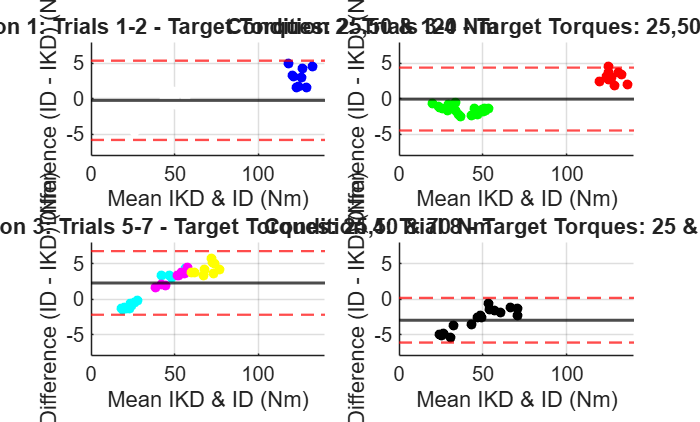

figure;

trial_groups = {
    [1 2];
    [3 4];
    [5 6 7];
    8
};

titles = {
    'Condition 1: Trials 1-2 - Target Torques: 25,50 & 120 Nm',
    'Condition 2: Trials 3-4 - Target Torques: 25,50 & 120 Nm',
    'Condition 3: Trials 5-7 - Target Torques: 25,50 & 70 Nm',
    'Condition 4: Trial 8 - Target Torques: 25 & 70 Nm'
};

for g = 1:4

    subplot(2,2,g); hold on;

    % reset accumulator
    ALL_MeanBA = [];
    ALL_DiffBA = [];
    ALL_A_peaks = [];
    ALL_B_peaks = [];

    trials = trial_groups{g};

    for trial = trials

        switch trial
            case 1
                T_Est = abs(Torque_GRF_01);
                T_Dyn = abs(Torque_dynamometer_shifted);
            case 2
                T_Est = abs(Torque_GRF_02);
                T_Dyn = abs(Torque_dynamometer_100Hz_02(810:end));
            case 3
                T_Est = abs(Torque_GRF_03);
                T_Dyn = abs(Torque_dynamometer_shifted_03);
            case 4
                T_Est = abs(Torque_GRF_04);
                T_Dyn = abs(Torque_dynamometer_100Hz_04(1000:end));
            case 5
                T_Est = abs(Torque_GRF_05);
                T_Dyn = abs(Torque_dynamometer_100Hz_05(3630:end));
            case 6
                T_Est = abs(Torque_GRF_06);
                T_Dyn = abs(Torque_dynamometer_shifted_06);
            case 7
                T_Est = abs(Torque_GRF_07);
                T_Dyn = abs(Torque_dynamometer_100Hz_07(1010:end));
            case 8
                T_Est = abs(Torque_GRF_08);
                T_Dyn = abs(Torque_dynamometer_100Hz_08(1420:end));
        end

        min_len = min(length(T_Est), length(T_Dyn));
        T_Est = T_Est(1:min_len);
        T_Dyn = T_Dyn(1:min_len);

        min_peak_height   = min_peak_params(trial,1);
        min_peak_distance = min_peak_params(trial,2);

        [pks_B, locs_B] = findpeaks(T_Dyn, ...
            'MinPeakHeight', min_peak_height, ...
            'MinPeakDistance', min_peak_distance);

        pks_A = T_Est(locs_B);

        valid = (pks_A > 0) & (pks_B > 0);
        A = pks_A(valid);
        B = pks_B(valid);

        % ====== Bland–Altman ======
        MeanBA = (A + B) / 2;
        DiffBA = (A - B);

        scatter(MeanBA, DiffBA, 35, colors(trial), 'filled');

        ALL_MeanBA = [ALL_MeanBA; MeanBA(:)];
        ALL_DiffBA = [ALL_DiffBA; DiffBA(:)];
        ALL_A_peaks = [ALL_A_peaks; A(:)];
        ALL_B_peaks = [ALL_B_peaks; B(:)];
    end

    bias = mean(ALL_DiffBA);
    sdDiff = std(ALL_DiffBA);
    loa_upper = bias + 1.96*sdDiff;
    loa_lower = bias - 1.96*sdDiff;

    yline(bias, 'k-', 'LineWidth', 1.8);
    yline(loa_upper, 'r--', 'LineWidth', 1.4);
    yline(loa_lower, 'r--', 'LineWidth', 1.4);
    xlim([0 140]);
    ylim([-8 8]); 
    grid on;
    xlabel('Mean IKD & ID (Nm)', 'FontSize', 12);
    ylabel('Difference (ID - IKD) (Nm)', 'FontSize', 12);
    title(titles{g}, 'FontSize', 13);
    set(gca, 'FontSize', 12);

end